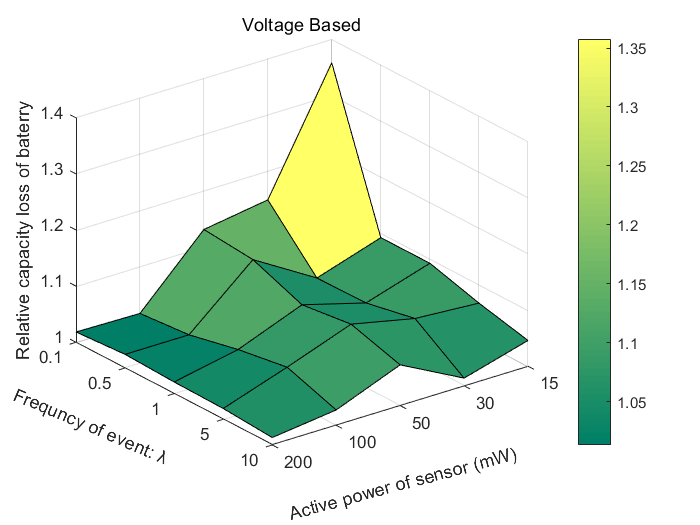

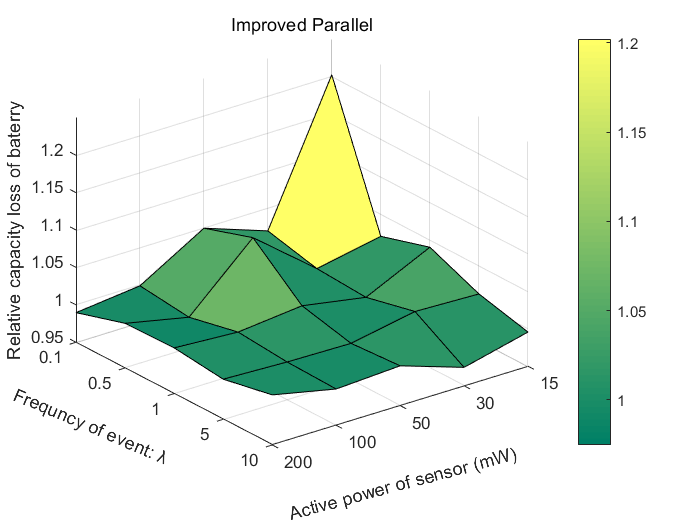

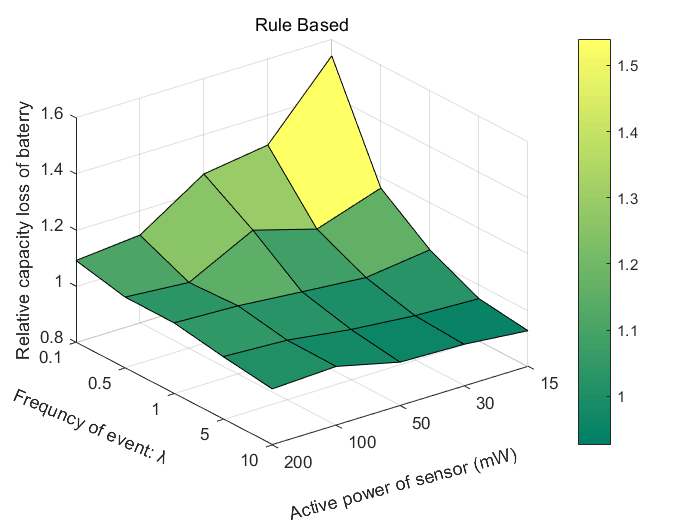

Qlossn = Qloss;
for i=1:4
    Qlossn(:,:,i) = Qloss(:,:,i)./Qloss(:,:,1);
end
management = {'SC First','Voltage Based','Improved Parallel','Rule Based'};
for j=2:4
    figure(j),surf(Qlossn(:,:,j));
    title(management(j))
    colormap summer
    colorbar('location','eastoutside')
    xlabel('Active power of sensor (mW)','Rotation',15) % x-axis label
    ylabel('Frequncy of event: λ','Rotation',-23) % y-axis label
    zlabel('Relative capacity loss of baterry') % y-axis label
    set(gca,'XDir','reverse','YDir','reverse')
    set(gca,'Xtick',1:5,'Ytick',1:5);
    set(gca,'Xticklabel',{'15','30','50','100','200'},'Yticklabel',{'0.1','0.5','1','5','10'});
    saveas(gcf,['E:\qnj\科研\03复合能量收集\建模与仿真\仿真程序\我的模型\EnergySystem\Figures\能源系统\2018.10.30\3D\' num2str(j) '.png']);
end